# HW5 Q_1 Sadra Safaei 401107198

## G

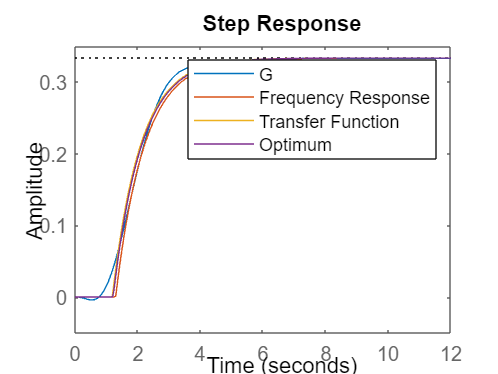

clc;
clear;

s = tf('s');
G = (-s+4)/((s+1)*(s+3)*(s^2 + 2*s +4));


% Frequency Response methode
[K_F , L_F, T_F] = get_fod (G);
G_F = K_F*exp(-L_F*s) /(T_F*s+1);

% Transfer Function methode
[K_T,L_T,T_T] = get_fod (G,1);
G_T = K_T*exp(-L_T*s) /(T_T*s+1);

% Optimum methode
G_O = opt_app(G, 0, 1, 1);

hold on;
step(G);
step(G_F);
step(G_T);
step(G_O);

legend ('G' , 'Frequency Response' , 'Transfer Function', 'Optimum')

## Controllers PID

clc;
clear;
close all;
s = tf('s');
G = (-s+4)/((s+1)*(s+3)*(s^2 + 2*s +4));
% Transfer Function methode
[K_T,L_T,T_T] = get_fod (G,1);
G_T = K_T*exp(-L_T*s) /(T_T*s+1);
N = 10;
vars = [K_T,L_T,T_T, N];
% 1) ZN PID =>ziegler_nic with key = 3 
[Gc_ZN, ~, ~, ~, ~] = ziegler_nic(3, vars);
G_ZN = feedback(G * Gc_ZN, 1);
%step(G_ZN)

% 2) refined ZN PID => rziegler_nic
[K_c , pp , w_c , w_g] = margin(G_T);
T_c = (2*pi)/w_c;
vars = [K_T,L_T,T_T, N, K_c, T_c];
[Gc_rZN, H,  ~, ~, ~, beta] = rziegler_nic(vars);

G_rZN = feedback(G * Gc_rZN, H);
%hold on
%step(G_rZN)


% 3) Modified ZN PID => ziegler_nic with key = 3 , using rb & pb
% for Pb
rb = 0.5;
[K_c , pp , w_c , w_g] = margin(G_T);
T_c = (2*pi)/w_c;
% figure(1)
% hold on
% for Pb = 10:5:20
%     vars = [K_c, T_c, rb, Pb, N];
%     [Gc_mZN, H, Kp, Ti, Td] = ziegler_nic(3, vars);
%     G_mZN = feedback(G * Gc_mZN, 1);
%     step(G_mZN);
% end
% hold off
% close
% for rb
% Pb = 15;
% figure(1)
% hold on
% for rb = 0.4:0.1:0.6
%     vars = [K_c, T_c, rb, Pb, N];
%     [Gc_mZN, H, Kp, Ti, Td] = ziegler_nic(3, vars);
%     G_mZN = feedback(G * Gc_mZN, 1);
%     step(G_mZN);
% end
% hold off
%close

rb = 0.5;
Pb = 15;

vars = [K_c, T_c, rb, Pb, N];
[Gc_mZN, ~, ~, ~, ~] = ziegler_nic(3, vars);
G_mZN = feedback(G * Gc_mZN, 1);
%step(G_mZN)

% 4) CC PID => key = 3 , type = 1
vars = [K_T,L_T,T_T, N];
[Gc_CC, ~, ~, ~, ~] = cohen_pid(3, 1, vars);
G_CC = feedback(G * Gc_CC, 1);

% 5) CC revisited PID => key = 3 , type = 2
vars = [K_T,L_T,T_T, N];
[Gc_CCr, ~, ~, ~, ~] = cohen_pid(3, 2, vars);
G_CCr = feedback(G * Gc_CCr, 1);

% 6) AH PID => key = 2 , type = 1
vars = [K_T,L_T,T_T, N];
[Gc_AH, ~, ~, ~, ~] = astrom_hagglund(2, 1, vars);
G_AH = feedback(G * Gc_AH, 1);

% 7) AH frecuency Based PID => key = 2 , type = 2
[K_c , pp , w_c , w_g] = margin(G_T);
T_c = (2*pi)/w_c;
vars = [K_T,K_c,T_c, N];
[Gc_AHf, ~, ~, ~, ~] = astrom_hagglund(2, 2, vars);
G_AHf = feedback(G * Gc_AHf, 1);

% Part 2
% 8) CHR set point (0% Os) PID => key = 3, type = 1
Os = 0;
vars = [K_T,L_T,T_T, N, Os];
[Gc_CHR0, ~, ~, ~, ~] = chr_pid(3, 1, vars);
G_CHR0 = feedback(G * Gc_CHR0, 1);

% 9) CHR set point (20% Os) PID => key = 3, type = 1
Os = 20;
vars = [K_T,L_T,T_T, N, Os];
[Gc_CHR20, ~, ~, ~, ~] = chr_pid(3, 1, vars);
G_CHR20 = feedback(G * Gc_CHR20, 1);

% 10) WJC
vars = [K_T,L_T,T_T, N];
[Gc_WJC, ~, ~, ~] = wjcpid(vars);
G_WJC = feedback(G * Gc_WJC, 1);

% 11) OPT setpoint PID & ISTE => key = 3 & type = 1 & C = 2
C = 2;
vars = [K_T,L_T,T_T, N, C];
[Gc_OPT_PID, ~, ~, ~] = opt_pid(3, 1, vars);
G_OPT_PID = feedback(G * Gc_OPT_PID, 1);

% 12) OPT setpoint PI-D & ISTE => key = 4 & type = 1 & C = 2
C = 2;
vars = [K_T,L_T,T_T, N, C];
[Gc_OPT_PI_D, H, ~, ~] = opt_pid(4, 1, vars);
G_OPT_PI_D = feedback(G * Gc_OPT_PI_D, H);


## Step Rsponse

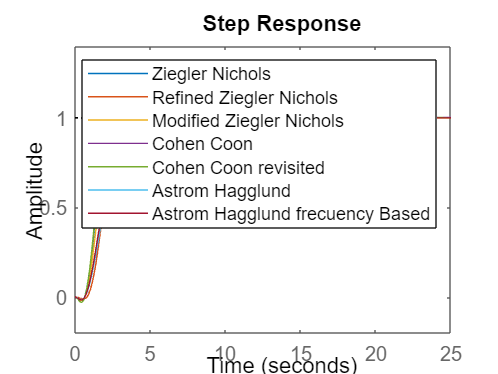

% Part 1
step(G_ZN, G_rZN, G_mZN, G_CC, G_CCr, G_AH, G_AHf)
legend ('Ziegler Nichols', 'Refined Ziegler Nichols', 'Modified Ziegler Nichols', ...
   'Cohen Coon', 'Cohen Coon revisited', 'Astrom Hagglund', ...
   'Astrom Hagglund frecuency Based')

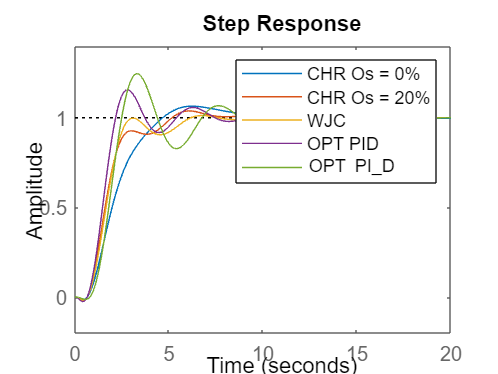


% Part 2
step(G_CHR0, G_CHR20, G_WJC, G_OPT_PID, G_OPT_PI_D)
legend ('CHR Os = 0%', 'CHR Os = 20%', 'WJC', 'OPT PID', 'OPT PI_D')

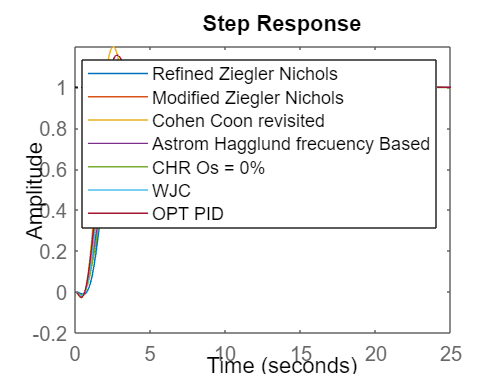


% Selected
step(G_rZN, G_mZN, G_CCr, G_AHf, G_CHR0, G_WJC, G_OPT_PID)
legend ('Refined Ziegler Nichols', 'Modified Ziegler Nichols', ...
   'Cohen Coon revisited', 'Astrom Hagglund frecuency Based', ...
   'CHR Os = 0%', 'WJC', 'OPT PID')